# Отчет №1: МКЭ для ОДУ второго порядка

*Баталов Семен, вариант 2, 451, 2022*

## Постановка задачи

Требуется реализовать метод конечных элементов (МКЭ) для обыкновенного дифференциального уравнения второго порядка:


$$-p(x)y''(x) + r(x)y(x) = f(x), \quad x \in [0, \, 1], \quad y(0) = y(1) = 0.$$


Общий вид ДУ:


$$-(a(x)u')' + c(x)u = f(x), \quad x \in [0, \, 1], \quad u(0) = u(1) = 0.$$


Обобщенная постановка краевой задачи Ш-Л:


$$\int_{0}^{1}(au'v' + cuv)dx = \int_{0}^{1}fvdx, \quad u, v \in H_{0}^{1}(0, 1).$$


Ищем решение в пространстве $V_h \;\left(0,1\right)$, выбираем соответствующий базис $\phi_1 ,\;\ldotp \ldotp \ldotp ,\;\phi_{N-1}$. Тогда предыдущее уравнение равносильно следующим уравнениям:


$$\int_{0}^{1}(a(x)u_{i}\phi_{i}'\phi_{j}' + c(x)u_{i}\phi_{i}\phi_{j})dx = \int_{0}^{1}f(x)\phi_{j}dx, \quad  i \in \{1, \ldots, N - 1\}.$$


Можем записать эти уравнения в матричной форме:


$$Ku = F,\\
K = A + C, \quad A_{ij} = \int_{0}^{1}a(x)\phi_{i}'\phi_{j}'dx, \quad C_{ij} = \int_{0}^{1}c(x)\phi_{i}\phi_{j}dx, \quad F_{i} = \int_{0}^{1}f(x)\phi_{i}dx.$$


Для решения системы с трехдиагональной матрицей будем использовать следующие методы:

- Метод прогонки;

- Итерационный алгоритм;

- Распараллеленный точный алгоритм (метод декомпозиции области).

Исходное уравнение:


$$$-y''(x) + \frac{2}{(1 + x)^2}y(x) = \frac{9}{(1 + x)^{3/2}}, \quad  x \in [0, \, 1], \quad y(0) = y(1) = 0.$$$


## Замечания

Стоит отметить, что мы не будем рассматривать *метод итераций Якоби* для больших дроблений промежутка, ограничимся случаями $N=100$ и $N=1600$. Причиной этому являются крайне высокие затраты машинного времени для достижения приемлемой точности.

В связи с этим на всех графиках решений для случаев $N=10000$, $N=160000$, $N=640000$ будем считать $U_2 \left(x\right)\equiv 0$, на графике эффективности алгоритмов изобразим только часть кривой для метода Якоби.

## Инициализация

Устанавливаем экспоненциальную форму вывода чисел:

format shortE

Устанавливаем настроечные параметры:

% Максимальное расстояние Чебышева между k-ым и (k-1)-ым решениями
err = [1.0e-7; 1.0e-8; 1.0e-9; 1.0e-11; 1.0e-11];

% Ограничение на количество итераций в методе Якоби
critNum = [1.0e6; 3.0e6; 0; 0; 0];

% Вектор количества элементов для всех экспериментов
N = [100; 1600; 10000; 160000; 640000];

Расчет вспомогательных величин:

h = 1 ./ N;
step = N / 5;
T = zeros(size(N, 1), 3);

Заданные функции:

p = @(x) 1.0 .* ones(size(x));
r = @(x) 2 ./ (1 + x) .^ 2 .* ones(size(x));
f = @(x) 9 ./ (1 + x) .^ 1.5 .* ones(size(x));

## Решение задачи

Основной цикл:


## Результат [N=100] :



ans = 6×7 table
        x           U1(x)         U2(x)         U3(x)          A, C            B             F     
    __________    __________    __________    __________    ___________    __________    __________

    0.0000e+00    0.0000e+00    0.0000e+00    0.0000e+00            NaN           NaN           NaN
    2.0000e-01    4.1459e-01    4.1448e-01    4.1459e-01    -9.9998e+01    2.0001e+02    6.8465e-02
    4.0000e-01    5.7418e-01    5.7400e-01    5.7418e-01    -9.9998e+01    2.0001e+02    5.4331e-02
    6.0000e-01    5.3792e-01    5.3775e-01    5.3792e-01    -9.9999e+01    2.0001e+02    4.4470e-02
    8.0000e-01    3.3959e-01    3.3948e-01    3.3959e-01    -9.9999e+01    2.0000e+02    3.7268e-02
    1.0000e+00    0.0000e+00    0.0000e+00   

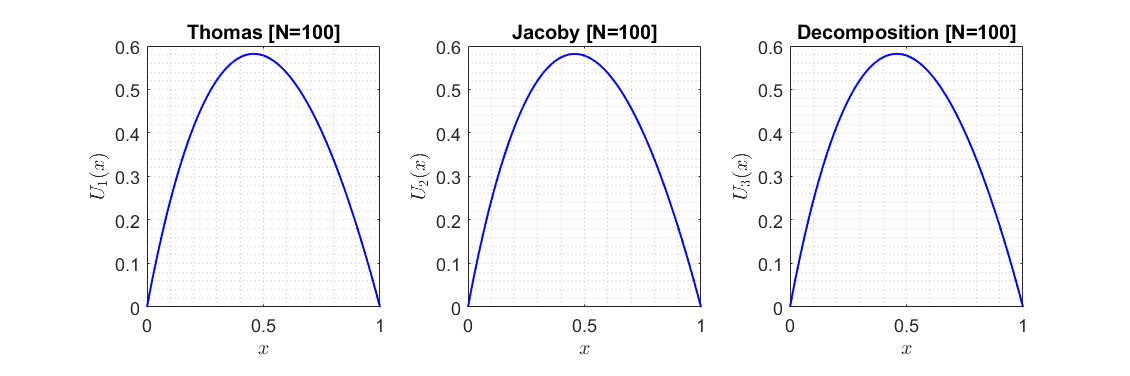


## Результат [N=1600] :



ans = 6×7 table
        x           U1(x)         U2(x)         U3(x)          A, C            B             F     
    __________    __________    __________    __________    ___________    __________    __________

    0.0000e+00    0.0000e+00    0.0000e+00    0.0000e+00            NaN           NaN           NaN
    2.0000e-01    4.1459e-01    4.1184e-01    4.1459e-01    -1.6000e+03    3.2000e+03    4.2791e-03
    4.0000e-01    5.7418e-01    5.6969e-01    5.7418e-01    -1.6000e+03    3.2000e+03    3.3957e-03
    6.0000e-01    5.3793e-01    5.3340e-01    5.3793e-01    -1.6000e+03    3.2000e+03    2.7793e-03
    8.0000e-01    3.3959e-01    3.3677e-01    3.3959e-01    -1.6000e+03    3.2000e+03    2.3292e-03
    1.0000e+00    0.0000e+00    0.0000e+00   

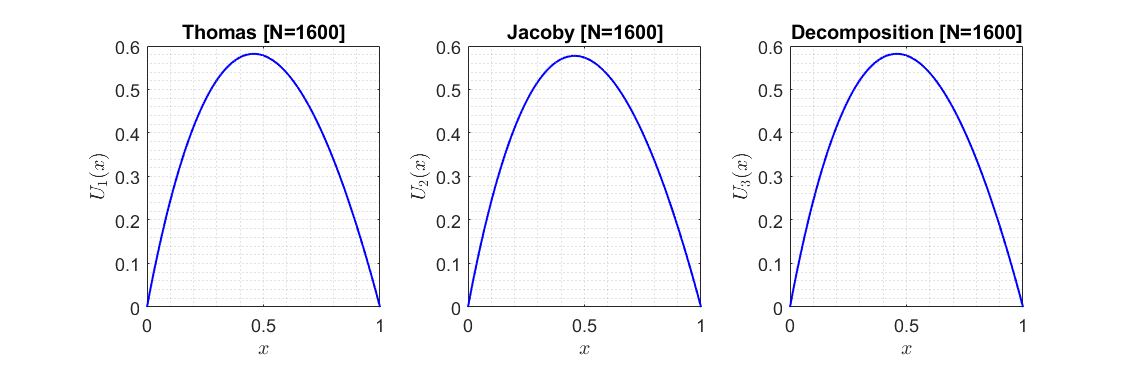


## Результат [N=10000] :



ans = 6×7 table
        x           U1(x)         U2(x)         U3(x)          A, C            B             F     
    __________    __________    __________    __________    ___________    __________    __________

    0.0000e+00    0.0000e+00    0.0000e+00    0.0000e+00            NaN           NaN           NaN
    2.0000e-01    4.1459e-01    0.0000e+00    4.1459e-01    -1.0000e+04    2.0000e+04    6.8465e-04
    4.0000e-01    5.7418e-01    0.0000e+00    5.7418e-01    -1.0000e+04    2.0000e+04    5.4331e-04
    6.0000e-01    5.3793e-01    0.0000e+00    5.3793e-01    -1.0000e+04    2.0000e+04    4.4470e-04
    8.0000e-01    3.3959e-01    0.0000e+00    3.3959e-01    -1.0000e+04    2.0000e+04    3.7268e-04
    1.0000e+00    0.0000e+00    0.0000e+00   

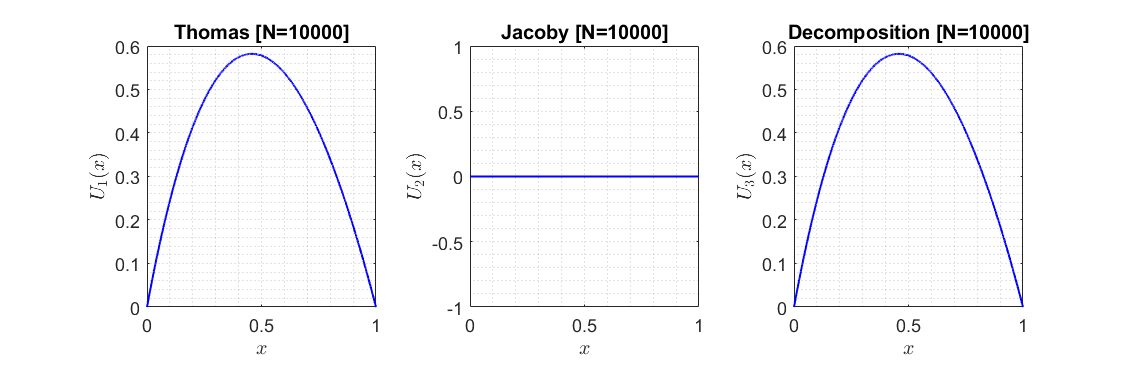


## Результат [N=160000] :



ans = 6×7 table
        x           U1(x)         U2(x)         U3(x)          A, C            B             F     
    __________    __________    __________    __________    ___________    __________    __________

    0.0000e+00    0.0000e+00    0.0000e+00    0.0000e+00            NaN           NaN           NaN
    2.0000e-01    4.1459e-01    0.0000e+00    4.1459e-01    -1.6000e+05    3.2000e+05    4.2791e-05
    4.0000e-01    5.7418e-01    0.0000e+00    5.7418e-01    -1.6000e+05    3.2000e+05    3.3957e-05
    6.0000e-01    5.3793e-01    0.0000e+00    5.3793e-01    -1.6000e+05    3.2000e+05    2.7793e-05
    8.0000e-01    3.3959e-01    0.0000e+00    3.3959e-01    -1.6000e+05    3.2000e+05    2.3292e-05
    1.0000e+00    0.0000e+00    0.0000e+00   

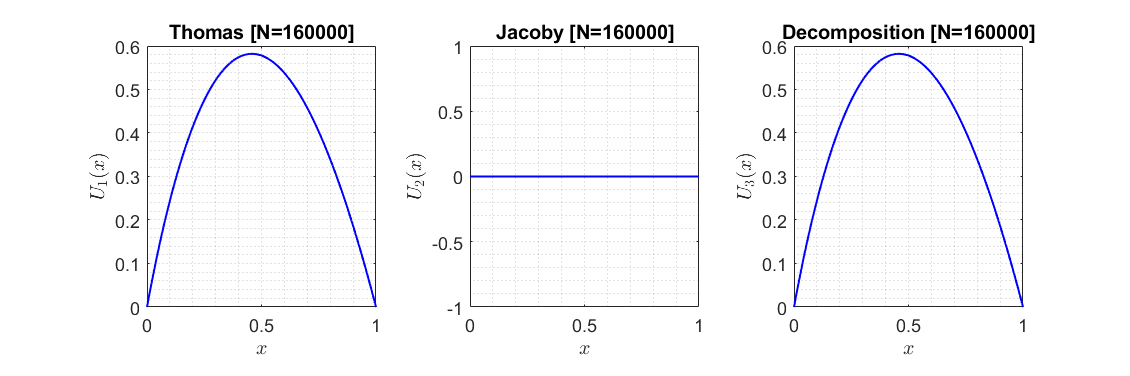


## Результат [N=640000] :



ans = 6×7 table
        x           U1(x)         U2(x)         U3(x)          A, C            B             F     
    __________    __________    __________    __________    ___________    __________    __________

    0.0000e+00    0.0000e+00    0.0000e+00    0.0000e+00            NaN           NaN           NaN
    2.0000e-01    4.1459e-01    0.0000e+00    4.1459e-01    -6.4000e+05    1.2800e+06    1.0698e-05
    4.0000e-01    5.7418e-01    0.0000e+00    5.7418e-01    -6.4000e+05    1.2800e+06    8.4893e-06
    6.0000e-01    5.3793e-01    0.0000e+00    5.3793e-01    -6.4000e+05    1.2800e+06    6.9484e-06
    8.0000e-01    3.3959e-01    0.0000e+00    3.3959e-01    -6.4000e+05    1.2800e+06    5.8231e-06
    1.0000e+00    0.0000e+00    0.0000e+00   

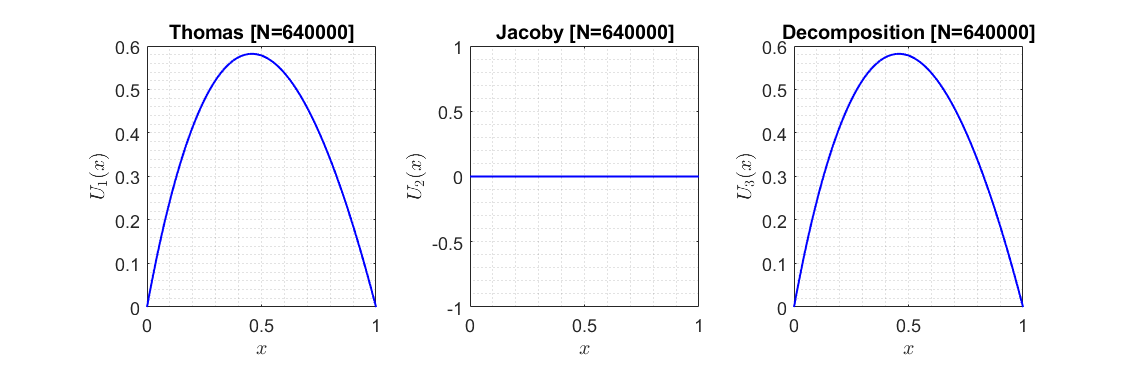

for i = 1:1:size(N, 1)
    
    % Формируем трехдиагональную матрицу и столбец свободных членов
    [K, F] = create_system(p, r, f, N(i), h(i));

    % Находим искомую функцию различными методами
    [U1, T(i, 1)] = thomas_algorithm(K, F, N(i));
    [U2, T(i, 2)] = jacoby_algorithm(K, F, N(i), 1, err(i), critNum(i));
    [U3, T(i, 3)] = parallel_algorithm(K, F, N(i));
    U1 = [0; U1; 0];
    U2 = [0; U2; 0];
    U3 = [0; U3; 0];
    X = (0:h(i):1)';

    % Вывод таблиц функций, построение графиков
    fprintf(strcat('\n## Результат [N=', num2str(N(i)), '] :\n\n'));
    output(X, U1, U2, U3, K, F, N(i), step(i));
end

График эффективности алгоритмов:

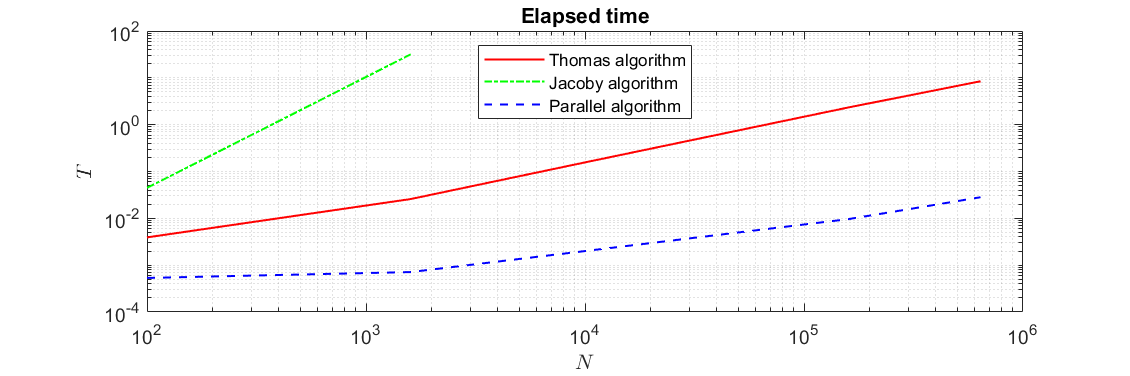

time(N, T);

## Вспомогательные функции

Процедура построения графиков решений:

function output(X, U1, U2, U3, K, F, N, step)
    
    % Временные переменные
    A = [NaN; 0; diag(K, -1); NaN];
    B = [NaN; diag(K, 0); NaN];
    D = [NaN; F; NaN];

    % Вывод таблицы значений в консоль
    table(X(1:step:N + 1), U1(1:step:N + 1), U2(1:step:N + 1), ...
        U3(1:step:N + 1), A(1:step:N + 1), B(1:step:N + 1), ...
        D(1:step:N + 1), 'VariableNames', ...
        {'x', 'U1(x)', 'U2(x)', 'U3(x)', 'A, C', 'B', 'F'})
    
    % Инициализация полотна
    figure('Name', 'Results', 'Position', [50, 150, 1200, 400]);
    tiledlayout(1, 3);
    
    % Первый график (Метод прогонки)
    ax1 = nexttile;
    plot(ax1, X, U1, '-b', 'LineWidth', 1)
    title(strcat('Thomas [N= ', num2str(N), ']'))
    ylabel('$U_1(x)$', 'Interpreter', 'latex')
    xlabel('$x$', 'Interpreter', 'latex')
    grid minor

    % Второй график (Метод Якоби)
    ax2 = nexttile;
    plot(ax2, X, U2, '-b', 'LineWidth', 1)
    title(strcat('Jacoby [N= ', num2str(N), ']'))
    ylabel('$U_2(x)$', 'Interpreter', 'latex')
    xlabel('$x$', 'Interpreter', 'latex')
    grid minor

    % Третий график (Метод распараллеливания)
    ax3 = nexttile;
    plot(ax3, X, U3, '-b', 'LineWidth', 1)
    title(strcat('Decomposition [N= ', num2str(N), ']'))
    ylabel('$U_3(x)$', 'Interpreter', 'latex')
    xlabel('$x$', 'Interpreter', 'latex')
    grid minor
end

Процедура построения графика эффективности алгоритмов:

function time(N, T)
    figure('Name', 'Elapsed time', 'Position', [50, 150, 1200, 400]);
    loglog(N, T(1:end, 1), '-r', N(1:2), T(1:2, 2), '-.g', N, ...
        T(1:end, 3), '--b', 'LineWidth', 1)
    title('Elapsed time')
    ylabel('$T$', 'Interpreter', 'latex')
    xlabel('$N$', 'Interpreter', 'latex')
    legend('Thomas algorithm', 'Jacoby algorithm', ...
        'Parallel algorithm', 'Location', 'north')
    grid minor
end